# **First Steps with the Toolbox**

**Loading data, creating a mass spectrum, defining ions and ranges, and allocating ions and atoms from the data**

This live script will guide the user through the first steps of generation of a mass spectrum and the definition of ions and ranges of an atom probe data set and their use to allocate ions and atoms in a pos variable with this toolbox.

The analysis of atom probe data in the toolbox is always based on three "ground truths". The third one is optional and only used to search for unknown ions.

- the isotope table, containing all isotopes and their abundances

- the colorScheme, upon which many outputs are consistantly colored

- the ionTable, a list of ions that could be in the mass spectrum

**This document is only showing the parts of the functionality of the individual algorithms/functions. To discover the full functionality, consult the further documentation and the function *****help*****.**

## Loading of data and ground truths

To have the necessary ground truths available, pre-supplied versions are supplied with the toolbox and can be loaded from it. Specifically, an isotope table with the isotopes and natural abundances of all elements according to the Commission on Isotopic Abundances and Atomic Weights of the International Union of Pure and Applied Chemistry ([https://www.ciaaw.org/](https://www.ciaaw.org/)) is supplied. Adjust as needed for isotopic experiments, mono-isotopic FIBs etc. 

Color schemes for light and dark backgrounds are also supplied. It is recommended to adjust them if one or more of the used ions are too close in color. The colors are in (r,g,b) with the value range of 0-1. Any ion that is not present in the color scheme but used in the analysis will need to be added to the color scheme.

As the analysis data, a *.pos or *.epos file can be loaded. A window will pop-up and prompt the user to choose a file. If the user wants to load an *.epos file, the selection in the selection window (buttom right) needs to be changed to *.epos. 

load isotopeTable_naturalAbundances.mat
load colorScheme.mat
posIn = posToTable;

## Creating a mass spectrum

When the pos or epos file is loaded, the mass spectrum can be plotted. The bin width and the plotting mode can be changed. Possible modes are *'count'* and *'normalised'*.

*'count'* shows the number of detected counts per bin over the mass-to-charge ratio, *'normalised'* records the number of counts as if the bin was 1 Da wide over the total number of counts.

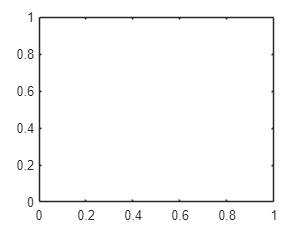

Unrecognized method, property, or field 'UserData' for class 'matlab.graphics.GraphicsPlaceholder'.

Error in massSpecPlot (line 60)
handle.UserData.plotType = "massSpectrum";

bin = 0.04; % bin width of the steps in which the plot is performed
mode = 'normalised' ; % specifies the way the counts are applied


 spec = massSpecPlot(posIn,bin,mode); % plots the mass spectrum

**Accessing a saved mass spectrum figure**

For almost all features of this toolbox, the user will need a mass spectrum as a basis for further evaluation and analyses. In order to easily access a saved mass spectrum figure, the user has to open the figure and select the mass spectrum by clicking on it in the 'Edit Mode' (the arrow key must be selected). 

In order to create an object handle (in this case called *spec*), the user has to execute following command:

spec = gco;

By doing so, the current object (selected mass spectrum) is assgned to *spec*. Now the user is ready to continue with the desired analysis. 

## Adding ions without knowledge of occurring ions

If the user does not know which ions were detected in the atom probe experiment, the function *ionFind* will be of much help. It will supply the user with a list of potential ions for a peak and lets the user cycle through them, always showing the isotopic abundance pattern in the mass spectrum. 

To execute this function, the user can create an ionTable which contains all possible ions (*ionsCreateComplex*). As inputs for this function, the user has to choose if *'all'* or only specified elements come into question. Additionally, the wanted charge states, the maximal complexity of the (molecular) ions, the complex formers, and the abundance threshold need to be defined.

An ionTable with many ions that have been observed in atom probe related publications is also supplied with the toolbox. (TODO)

elements = {'Ni','H','O','C'}; % can be a list of atomic numbers, symbols or 'all', pos.atom
complexity = [1 2]; % complexity of the created ions, as list e.g. [1 2]
chargeStates = [1 2 3 4 5]; % array of charge states
ionList = ionsCreateComplex(elements,complexity,isotopeTable,chargeStates);
 

After creating the ionTable, the addition of ion stem plots can be done with the function *ionFind*. Therefore, the user needs to execute the function and then select the wanted peak by drawing a rectangle over the peak. A pop-up window will appear, that indicates possible ions that matches the selected peak. The user can then choose the most suitable entry from the list.

searchRange = 0.3; % range in which suggested ions would have a peak, optional
ionFind(spec,ionList,isotopeTable,colorScheme,searchRange);
 

## Adding ions with knowledge of occurring ions

With the function *ionAdd*, the user can add stem plots of ions and their isotopic combinations to the mass spectrum. Specific information about the added ions can be found in the UserData section of the stem plot. 

To define an ion, several inputs are necessary. The first input is the plot handle of the mass spectrum plot (*spec*, as above), to which the ion stem plot will be plotted. For the definition of the ion, the name of the corresponding atom, the charge state (also possible as a vector of several charge states, but then no peak height snapping can be done), the margin within which two or more peaks will be summed up into one, and the minimal abundance below which peaks are discarded, need to be defined. Optionally, the height of the most abundant isotope, which can be chosen either as *'selection'* or *'most abundant'*, can be specified. For *'most abundant'*, the highest peak within the vicinity of *maxSeparation* Da will be used. This is the most common use.

% the user needs to execute the following command in the command line: spec = massSpecPlot(pos,bin,mode);
% and proceed with:
ion = 'C' % chemical symbol of the ion that will be added

ion = 'C'

chargeState = 1 % charge state of the ion, vector of charge states

chargeState = 1

sumMargin = 0.25 % specifies a margin within which two peaks will be summed up

sumMargin = 0.2500

minAbundance = 0.04 % is the minimal abundance

minAbundance = 0.0400

maxHeight = 'most abundant' % is the height of the most abundant isotope

maxHeight = 'most abundant'

maxSeparation = 1 % the maximum of the mass spectrum within this range will be used for scaling

maxSeparation = 1

ionAdd(spec,ion,chargeState,isotopeTable,colorScheme,sumMargin,minAbundance,maxHeight,maxSeparation) % ionAdd creates a stem plot in the mass spectrum (spec) for the parsed ion and its corresponding charge state(s)

ans =   Stem (C+) with properties:

              Color: [0.8555 0.6448 0.3763]
          LineStyle: '--'
          LineWidth: 2
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
          BaseValue: 1.0000e-05
              XData: 12
              YData: 1.3713e-04

  Show all properties


clearvars ion chargeState sumMargin minAbundance maxHeight maxSeparation
 

For deleting ion stem plots, the user simply needs to select them with the cursor in *Edit Plot* and press delete.

## Option: Adding ions from mass spectrum of similar data set

This way of adding ions is regularly used when occuring ions are already known from previous similar data sets. They can then be added by extracting the defined ions from the previous data set's ranging figure (*specPrevious*) using:

it = ionsExtractFromMassSpec(specOld); % extracting ions from previous mass spectrum (specPrevious)
for i=1:height(it) % looping through all defined ions
sumMargin = 0; % specifies a margin within which two peaks will be summed up
minAbundance = 0.01; % is the minimal abundance
maxSeparation = 0.1; % the maximum of the mass spectrum within this range will be used for scaling
ionAdd(spec,string(it.ionName(i)),it.chargeState(i),isotopeTable,colorScheme,sumMargin,minAbundance,'most abundant',maxSeparation);
end
clearvars chargeState sumMargin i ion it maxHeight maxSeparation minAbundance ans 
 

## Adding a single range

Subsequently, ranges can be added in the mass spectrum. With *rangeAdd*, ranges can be added one at a time. As input variables only the mass spectrum (*spec*) and the *colorScheme* are needed. Partial or total overlaps with already existing ranges are reported and the range is clipped accordingly, or rejected. 

If the range spans over defined ion peaks, either the ion will be chosen automatically (if there is only one) or a selection box will pop up with the default selection being the ion with the largest abundance.

If the range does not span over a defined ion, manual definition of the ion name is necessary. To this end, the range name must be supplied. If the range name is a valid ion including isotopic information, it will be treated as such. If the ion is unclear or unknown, a name that is not a valid ion and that does not contain numbers must be chosen, e.g. *manualName* = 'unknownA'. The use is then: *rangeAdd(spec,colorScheme,manualName)*. However, in order to ensure a proper functionality, a color code needs to be assign to the chosen *manualName* in *colorScheme*.

rangeAdd(spec,colorScheme); % the user can add a single range to the mass spectrum
 

Of course, not all detector hits represent ions, some may be detector noise or be attributed to cosmic radiation or radioactive decay in the microchannel plates. Ranges, that contain only this *'background'*, can also be added and labeled as such. This can be used for later analysis to explicitly deal with such noise artefacts.

rangeAdd(spec,colorScheme,'background'); % adds range denoting background

## Semi-automated ranging of the added ions

If the user does not want to execute the *rangeAdd* function all the time, only the *rangeAddAll* function has to be executed. This function will guide the user through the mass spectrum by consecutively pushing focus on each unranged ion. The user has the option to graphically define a minimum level below which peaks will not be considered. To enable this option, *useMin* needs to be set to *true*. This makes it possible to range even the most complex mass spectra in a matter of minutes. In order to skip the ranging of a peak, the user needs to press *Enter*.

rangeMargin = 3; % is the number of Da before and after the peak that are displayed
useMin = 'true';
rangeAddAll(spec,colorScheme,rangeMargin,useMin);
 

## Creating a legend for mass spectrum

The *massSpecShowLegend* command is available to the user to get a better overview of the data shown in the mass spectrum. This command creates a legend and makes it sortable so that only *ions* or *ranges* or both are shown.

items = "ion" % defines which information is written down in the legend
massSpecShowLegend(spec,items);
 

## Sorting the mass spectrum

With *massSpecReorderPlo*t, the user is given the opportunity to organize the information stored in the mass spectrum according to his wishes. The user can choose between *text*, *ion*, *range*, *background* and *massSpectrum*.

order = ["range","text","ion","background","massSpectrum","unknown"]; % set what kind of information stands in focus. if more informations are given order i9nformations can be in any order
massSpecReorderPlot(spec,order);
 

## Allocating the ions in an atom probe data set to the ranges

The goal of defining ranges in the mass spectrum is to chemically identify individual detector ions that have been recorded in an atom probe experiment. Since multiple atoms can form a single complex ion,it can be decided to work with the ions or the ions decomposed into their constituent atoms. For this, the ranges defined in a mass spectrum can be extracted into a table. This table can then be used to provide the information needed to allocate the hits of the mass spectrum.

rangeTable = rangesExtractFromMassSpec(spec); % extracts the ranges from the mass spectrum
option = "decompose";
pos = posAllocateRange(posIn,rangeTable,option);
 

With the function *posUnDecompose*, the user can create a pos table, in which the complex ions are not decomposed, but only the ranges are allocated. As input, a decomposed pos table is used. 

The output *posRaw* is identical with the output of the function *posAllocateRange* when using *'raw'* as the option input, see section above. This may come in handy if the initial pos table (*posIn*) was deleted by mistake or is not present in the workspace anymore for other reasons.

posRaw = posUnDecompose(pos);
 

## Extracting ions from a mass spectrum

The function *ionsExtractFromMassSpec *pulls all ions and corresponding information from a mass spectrum plot and gets all plots connected to the mass spectrum. The output *ionTable* is a table containing the ion names with charge state, elemental composition (in column *ion*) and assigned color code.

The created ion table can be used, for example, for the creation of a new color scheme, see the live script **ColorScheme** or the function *colorSchemeCreate*.

ionTable = ionsExtractFromMassSpec(spec); % extracting ions from a mass spectrum
 